global lamda a b c gamma
% Copper x-ray source wavelength
lamda  = 0.154181; %nm

% Approximated lattice parameters of 10M NMG, 
a  =  0.5974; % a, nm
b  =  0.5947; % b, nm
c  =  0.5581; % c, nm
gamma  =  90.36; % gamma, degrees

hkl = [1 1 1; 0 2 2; 2 2 0; 2 2 2; 0 0 4; 0 4 0; 2 2 4; 2 4 2; 0 4 4; 0 2 6; 4 4 0; 2 2 6; 0 6 2;2 6 2]

hkl =      1     1     1
     0     2     2
     2     2     0
     2     2     2
     0     0     4
     0     4     0
     2     2     4
     2     4     2
     0     4     4
     0     2     6


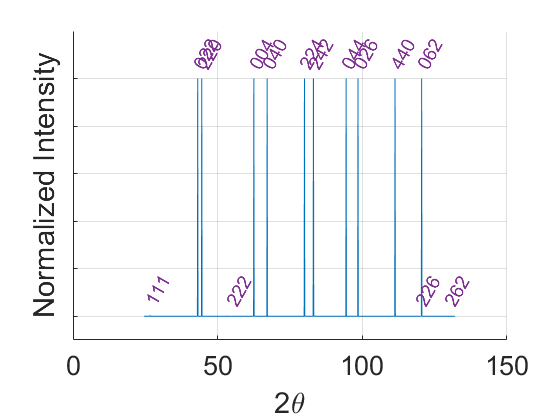

% Bragg angles for diffraction
angles = twotheta(hkl);

%%Convert to integers because matlab has problem matching
% I am only interested in 1 significant figures
angles = uint32(angles.*10);
% range of angles to plot
x = (min(angles)-20):(max(angles)+20);

% find the matching bragg angles
[~,ind] = intersect(x,angles);
% convert back to correct angles as a float
x = double(x)./10;

% Find peak intensities using Structure Factor @ theta = 0 degree
for i = 1 : size(hkl,1)
    SFhkl(i) = SF_FCNMG(hkl(i,:)); 
end

% The diffraction intensity
inten = conj(SFhkl).*SFhkl;
inten = inten ./ max(inten);
clear i SFhkl

y = 0 .* x;
y(ind) = inten;
clear inten

% Did it find all the peak angles?
if length(angles) ~= length(x(ind))
    error('The x-axis did not pick all the diffraction angles')
end
clear angles

% Plot the figure
figure, hold on
plot(x,y)
for k = 1:size(hkl,1)
    t = num2str(hkl(k,:));
    t = t(~isspace(t));
    text(x(ind(k)),y(ind(k))+0.05,t,'Rotation',60,"FontSize",14,'Color',[0.49,0.18,0.56])
end
clear t k ind
set(gcf,'color','w')
set(gca,'FontSize',20,'FontName','Helvetica')
ylim([-0.1 1.2])
yticklabels([])
xlabel('2\theta')
ylabel('Normalized Intensity')
grid on, box off, hold off


twothetas = x; intensity = y;
clear x y

function output = twotheta(A)
    
    global lamda a b c gamma
    % metric tensor for monoclinic lattice
    G = [a^2,a*b*cosd(gamma),0; a*b*cosd(gamma),b^2,0; 0,0,c^2];
    %  Reciprocal metric tensor
    Ginv = inv(G);
    
    if size(A,2) == 3
        for i = 1 : size(A,1)
            hkl = A(i,:);
            %%calculate the dspacings
            % g_hkl^2
            gsquared = hkl*Ginv*hkl';
            % d = 1 /g_hkl
            d = 1/sqrt(gsquared);
            % two-theta
            output(i) = 2*asind(lamda/(2*d));
        end
    else
        error('The hkl planes are not in correct form. Rows of row vector needed for calculation.')
    end
end

function output = SF_FCNMG (hkl)
    fNi = 59; fMn = 55; fGa = 70;
    lp = [0 0 0; 0.5 0.5 0; 0 0.5 0.5; 0.5 0 0.5];
    rGa = [0 0 0];
    rMn = [1/2 0 0];
    rNi1 = [1/4 1/4 1/4];
    rNi2 = [3/4 1/4 1/4];
    
    flp = 0;
    for j = 1 : size(lp,1)
        r = lp(j,:);
        flp = flp + ASF(hkl,r);
    end
    
    fmp = fGa*ASF(hkl,rGa) + ...
        fMn*ASF(hkl,rMn) + ...
        fNi * (ASF(hkl,rNi1) + ASF(hkl,rNi2));
    
    output = fmp * flp;
    
end

function output = ASF(hkl,r)
    output = exp(2*pi*1i*(hkl(1)*r(1) + hkl(2)*r(2) + hkl(3)*r(3)));
end